# Virtual Environments Exercise Solutions

### Exercise 17

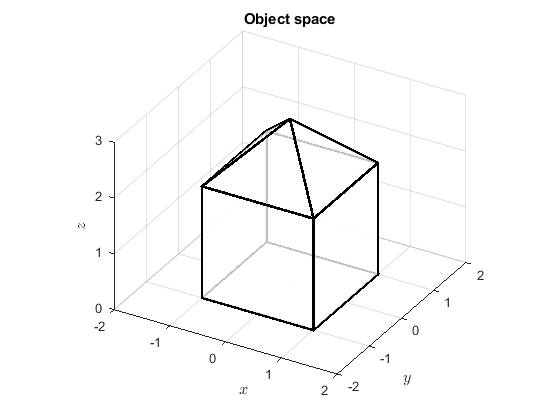

% Define object
Vobj = [ -1,  1,  1, -1, -1,  1,  1, -1,  0 ;
         -1, -1,  1,  1, -1, -1,  1,  1,  0 ;
          0,  0,  0,  0,  2,  2,  2,  2,  3 ;
          1,  1,  1,  1,  1,  1,  1,  1,  1];
Fobj = [ 4, 3, 2, 1 ;
         1, 2, 6, 5 ;
         2, 3, 7, 6 ;
         3, 4, 8, 7 ;
         5, 8, 4, 1 ;
         6, 5, 9, 9 ;
         6, 7, 9, 9 ;
         7, 8, 9, 9 ;
         8, 5, 9, 9 ];

% Plot object space
figure
patch('Vertices', Vobj(1:3,:)', 'Faces', Fobj, FaceColor='white', FaceAlpha=0.75, LineWidth=2)
title('Object space')
xlabel('$x$', 'Interpreter', 'latex', 'FontSize', 12)
ylabel('$y$', 'Interpreter', 'latex', 'FontSize', 12)
zlabel('$z$', 'Interpreter', 'latex', 'FontSize', 12)
view(30, 30)
axis equal
axis([-2, 2, -2, 2, 0, 3])
grid on 
exportgraphics(gcf,'../images/exercise_17.png', Resolution=300)

### Exercise 18

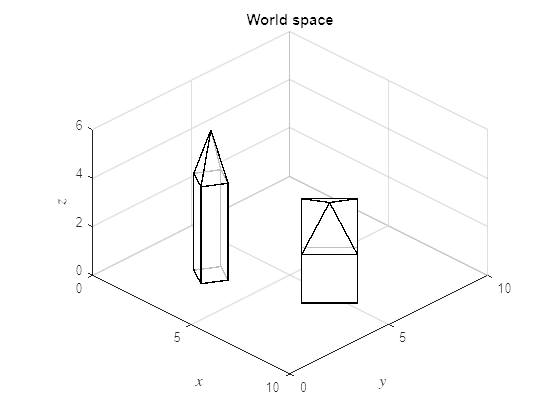

% Define object positions, scaling and rotations
p1 = [3 ; 3 ; 0];
p2 = [6 ; 6 ; 0];
s1 = [0.5 ; 0.5 ; 2];
s2 = [1 ; 2 ; 1];
rot1 = pi/3;
rot2 = pi/4;

% Define transformation matrices
T = @(t) [ 1, 0, 0, t(1) ;
           0, 1, 0, t(2) ;
           0, 0, 1, t(3) ;
           0, 0, 0, 1 ];
S = @(s) [ s(1), 0, 0, 0 ;
           0, s(2), 0, 0 ;
           0, 0, s(3), 0 ;
           0, 0, 0, 1 ];
Rz = @(theta) [ cos(theta), -sin(theta), 0, 0 ;
                sin(theta), cos(theta), 0, 0 ;
                0, 0, 1, 0 ;
                0, 0, 0, 1 ];

% Transform objects into world space
Fworld = Fobj;
Vworld = T(p1) * Rz(rot1) * S(s1) * Vobj;

Fworld = [Fworld ; Fobj + size(Vworld, 2)];
Vworld = [Vworld, T(p2) * Rz(rot2) * S(s2) * Vobj];

% Plot world space
figure
patch('Vertices', Vworld(1:3,:)', 'Faces', Fworld, FaceColor='white', FaceAlpha=0.75, LineWidth=1)
title('World space')
xlabel('$x$', 'Interpreter', 'latex', 'FontSize', 12)
ylabel('$y$', 'Interpreter', 'latex', 'FontSize', 12)
zlabel('$z$', 'Interpreter', 'latex', 'FontSize', 12)
view(45, 30)
axis equal
axis([0, 10, 0, 10, 0, 6])
grid on 

### Exercise 19

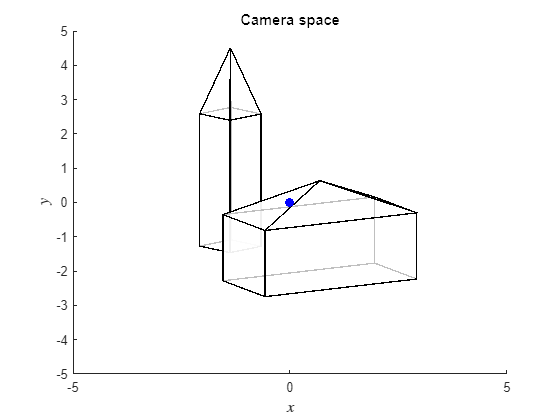

% Define viewing position and centre of view
p = [12 , 7 , 4];
c = [5 , 5 , 2];
k = [0 , 0 , 1];

% Calculate alignment matrix
w = (p - c) / norm(p - c);
u = cross(k, w) / norm(cross(k, w));
v = cross(w, u);
A = [ u, -dot(p, u) ; 
      v, -dot(p, v) ;
      w, -dot(p, w) ;
      0, 0, 0, 1 ];

% Align world space to the camera space
Vcamera = A * Vworld;

%Plot camera space
figure
h1 = axes;
patch("Vertices", Vcamera([1,3,2],:)', "Faces", Fworld, FaceColor="w", FaceAlpha=0.75, LineWidth=1)
hold on
plot3(0, 0, 0, "bo", MarkerFaceColor="b")
quiver3(0, 0, 0, 0, -1, 0, "b", MaxHeadSize=1)
hold off
set(h1, "Ydir", "reverse")  % reverse z axis so that it matches the right-hand rule
title('Camera space')
xlabel("$x$", "Interpreter", "latex", "FontSize", 12)
ylabel("$z$", "Interpreter", "latex", "FontSize", 12)
zlabel("$y$", "Interpreter", "latex", "FontSize", 12)
view(0,0)
axis([-5, 5, -15, 0, -5, 5])

### Exercise 20

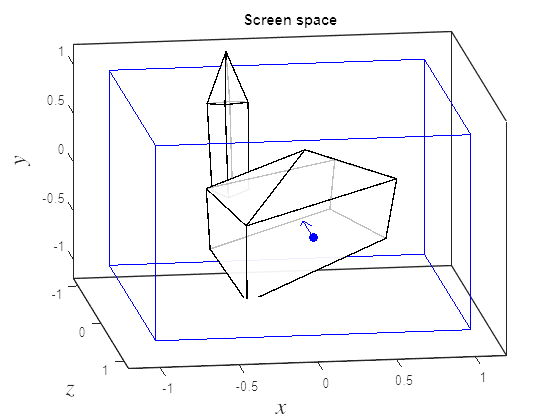

near = 2;
far = 10;
fov = pi/3;
aspect = 4/3;

% Calculate projection matrix
r = near * tan(fov / 2);
t = r / aspect;
P = [-near / r, 0, 0, 0 ;
     0, -near / t, 0, 0 ;
     0, 0, (near + far) / (near - far), 2 * near * far / (near - far) ;
     0, 0, 1, 0 ];

% Calculate screen space co-ordinates
Vscreen = P * Vcamera;
Vscreen = Vscreen ./ Vscreen(4,:);

% Plot screen space viewed from the side
figure()
h1 = axes;
patch("Vertices", Vscreen([1,3,2],:)', "Faces", Fworld, FaceColor="w", FaceAlpha=0.75, LineWidth=1)
patch("Vertices", Vfrustum(1:3,:)', "Faces", Fcube, FaceAlpha=0, EdgeColor="blue")
hold on
plot3(0, 1, 0,"bo",MarkerFaceColor="b")
quiver3(0, 1, 0, 0, -0.5, 0, "b", MaxHeadSize=1)
hold off
title('Screen space')
xlabel("$x$", "Interpreter", "latex", "FontSize", 18)
ylabel("$z$", "Interpreter", "latex", "FontSize", 18)
zlabel("$y$", "Interpreter", "latex", "FontSize", 18)
set(h1, "Ydir", "reverse")  % reverse z axis so that it matches the right-hand rule
view(0,0)
axis([-1.2, 1.2, -1.2, 1.2, -1.2, 1.2])
box